clear;

ball = @(R) 4/3*pi*(R^2)

ball = function_handle with value:
    @(R)4/3*pi*(R^2)


spike = @(r, b) pi*r*(r + b)

spike = function_handle with value:
    @(r,b)pi*r*(r+b)


p_eval = @(a, b) (a+2*b)/2

p_eval = function_handle with value:
    @(a,b)(a+2*b)/2



fun = @(x)((spike(x(1), x(2))/ball(R_eval(x(1), x(2)))))

fun = function_handle with value:
    @(x)((spike(x(1),x(2))/ball(R_eval(x(1),x(2)))))



Single objective optimization:
2 Variable(s)
1 Linear inequality constraint(s)

Options:
CreationFcn:       @gacreationlinearfeasible
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           14.85            7084        0
    2              147           14.85              21        0
    3              194           14.85           15.35        1
    4              241           14.85           14.95        2
    5              288           14.85           14.91        0
    6              335           14.85           14.87        0
    7              382           14.85           14.86        0
    8              429           14.85           14.86        1
    9              476           14.85           14.85        2
   10              523         

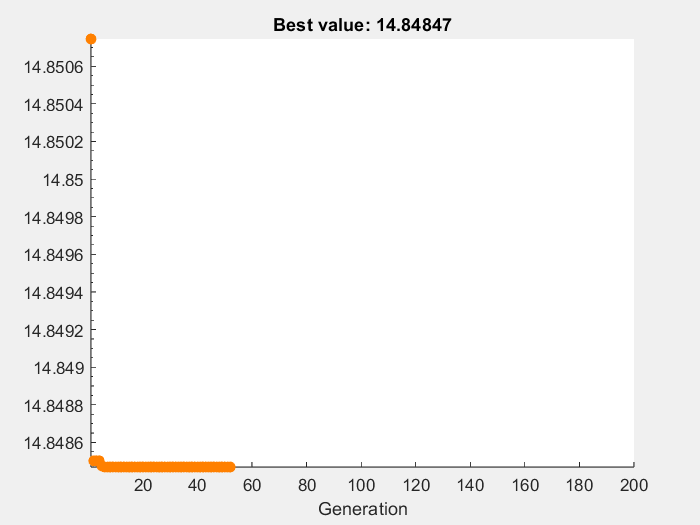

x =    53.3118   91.9493


fval = 14.8485

exitflag = 1

output = struct with fields:
      problemtype: 'linearconstraints'
         rngstate: [1×1 struct]
      generations: 52
        funccount: 2497
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0
       hybridflag: []


population =    53.3118   91.9493
   53.3118   91.9493
   53.3118   91.9493
   53.3118   91.9492
   53.3118   91.9494
   53.3118   91.9493
   53.3118   91.9493
   53.3119   91.9496
   53.3118   91.9492
   53.3118   91.9493


scores =    14.8485
   14.8485
   14.8485
   14.8485
   14.8485
   14.8485
   14.8485
   14.8485
   14.8485
   14.8485


A = [1, -1];
b = 0;

x0 = [20,90];
lb = [0.001, 0.001];
ub = [100,100];

options = optimoptions("ga",'PlotFcn', @gaplotchange, 'Display','iter');
options.InitialPopulationMatrix = x0;
[x,fval,exitflag,output,population,scores] = ga(fun, 2, A, b, [], [], lb, ub, [], [], options)


x(2)/x(1)

ans = 1.7247

ball(R_eval(x(1), x(2)))

ans = 1.6385e+03

function [R] = R_eval(a, b)
    p_eval = @(a, b)[(a+2*b)/2];
    p = p_eval(a, b);
    R = sqrt(((p-a)*(p-b)^2)/p);
end %function

function state = gaplotchange(options, state, flag)
persistent last_best
if(strcmp(flag,'init'))
xlim([1,options.MaxGenerations]);
axx = gca;
axx.YScale = 'log';
hold on;
xlabel Generation
X = sprintf('Best value: %.5f', min(state.Score));
title(X)
end
X = sprintf('Best value: %.5f', min(state.Score));
title(X)
best = min(state.Score);
plot(state.Generation,best,'o', 'MarkerFaceColor',[1 0.5 0], ...
'MarkerEdgeColor', [1 0.5 0]);
end